### 全chオシロ波形

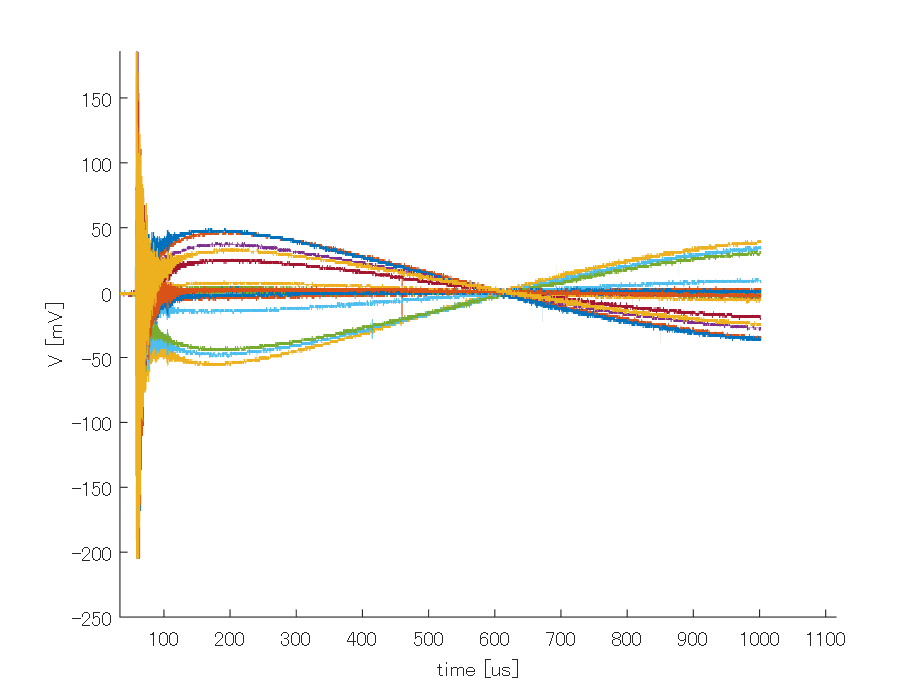

experiment_date = '230116';
data_directory = strcat('C:\Users\uswk0\OneDrive\ドキュメント\GitHub\test-open\道家\卒論\data\',experiment_date);


%filename = 'toroidal_mode20230114_101911_No1.csv'; %TF2kV
%filename = 'toroidal_mode20230114_105719_No4.csv';
%filename = 'toroidal_mode20230114_105225_No3.csv'; %PF20kV
%filename = 'toroidal_mode20230114_114006_No6.csv';
%filename = 'toroidal_mode20230114_124327_No7.csv';
%filename = 'toroidal_mode20230114_151259_No8.csv';
%filename = 'toroidal_mode20230115_193926_No8.csv';
%filename = 'toroidal_mode20230115_200819_No10.csv';
%filename = 'toroidal_mode20230115_192247_No6.csv';%PF39kV
%filename = 'toroidal_mode20230115_210102_No11.csv';
%filename = 'toroidal_mode20230116_111930_No5.csv';
filename = 'toroidal_mode20230116_111703_No3.csv';
%filename = 'toroidal_mode20230116_124903_No6.csv';
file_path = strcat(data_directory, '\', filename); 

M = readmatrix(file_path);
%disp(M);
t = M(:,1);

figure;
hold on;
plot(t, M(:,2:25)*10^3);
%legend('ch1','ch2','ch3','ch4','ch5','ch6','ch7','ch8','ch9','ch10','ch11','ch12','ch13','ch14','ch15','ch16','ch17','ch18','ch19','ch20','ch21','ch22','ch23','ch24');
xlim();
ylim();
xlabel('time [us]');
ylabel('V [mV]');
%title('TF39kV shot');
hold off;

### 各プローブごと (dBz/dt, dBt/dt, dBr/dt) 

%それぞれのプローブごとに(bz, bt, br)を表示
 plot_each_probe(M, 8);

## すべてのchの信号

total_ch = 24;
 %time
t = M(:,1);

%figure('Position','visible','on');
%較正係数(NSbz, NSbt, NSbr)
NSztr = [37.7, 41.6,133]*10^-6;
figure('Position', [0 0 800 800],'visible','on');
for i =1:total_ch
    subplot(4,6,i);
    
 
    if rem(i,3) == 1
        dbzdt = -M(:,i+1)/NSztr(1);
        plot(t, dbzdt);
        title(strcat('ch',num2str(i),' dBz/dt'));
        
    elseif rem(i,3) == 2
        dbtdt = -M(:,i+1)/NSztr(2);
        plot(t, dbtdt);
         title(strcat('ch',num2str(i),' dBt/dt'));
    else
        dbrdt = -M(:,i+1)/NSztr(3); 
        plot(t, dbrdt);
         title(strcat('ch',num2str(i),' dBr/dt'));
    end
    ylim([-500 500]);
    %xlim();
    %xlim([0 1000]);
    
end
total_ch = 24;
 %time
t = M(:,1);

%figure('Position','visible','on');
%較正係数(NSbz, NSbt, NSbr)
NSztr = [37.7, 41.6,133]*10^-6;
figure('Position', [0 0 800 300],'visible','on');
for i =1:total_ch
    subplot(4,6,i);
    
    if rem(i,3) == 1
        dbzdt = -M(:,i+1)/NSztr(1);
        plot(t, M(:,i+1));
        title(strcat('ch',num2str(i),' Vz'));
        
    elseif rem(i,3) == 2
        dbtdt = -M(:,i+1)/NSztr(2);
        plot(t, M(:,i+1));
         title(strcat('ch',num2str(i),' Vt'));
    else
        dbrdt = -M(:,i+1)/NSztr(3); 
        plot(t, M(:,i+1));
         title(strcat('ch',num2str(i),' Vr'));
    end
    %ylim([-500 500]);
    %xlim();
    xlim([35 50]);
    ylim([-0.2 0.2]);
    
end

%figure('Position', [0 0 100 800],'visible','on');
figure;
cnt = 1;
while cnt <= 8
for i =1:total_ch
    if rem(i,3) == 1       
        subplot(1,8,cnt)
        plot(t, -M(:,i+1)/NSztr(1));
        title(strcat('ch',num2str(i),' dBz/dt'));
        ylim([-400 400]);
        %xlim([300 600]);
        cnt = cnt+ 1;
    end
end
end

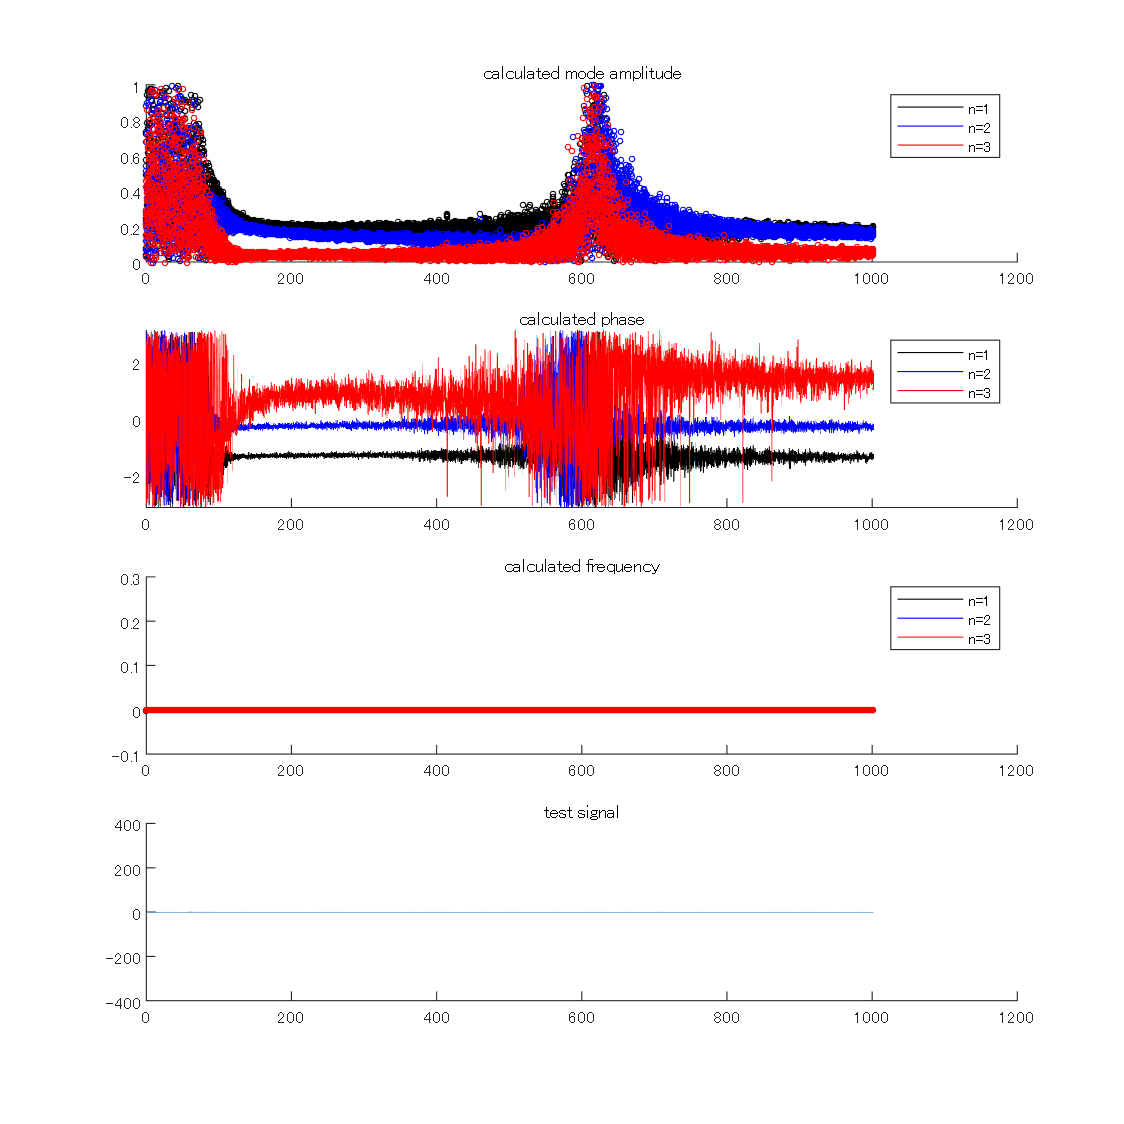

signal = M(:,2:3:23);

for i = 1:8
    i_bt = i*3;
    i_br = i*3+1;
    signal(:,i)=sqrt(M(:,i_bt).^2+M(:,i_br).^2);
end

x = [0,4/24,7/24,9/24,12/24,15/24,17/24,20/24]; % non-uniform probe placement
[n_Amp,n_Ph] = toroidal_mode(t,x,signal); % get amplitude and phase

% calculate frequency from phase (smoothed)
n1_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(1,:)),0.1,'loess'));
n2_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(2,:)),0.1,'loess'));
n3_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(3,:)),0.1,'loess'));

% *************** plotting ***************
figure('Position', [0 0 800 800]);
subplot(4,4,1:4)
hold on
plot(t,smooth(n_Amp(2,:)./n_Amp(1,:),0.1,'loess'),'k');
plot(t,smooth(n_Amp(3,:)./n_Amp(1,:),0.1,'loess'),'b');
plot(t,smooth(n_Amp(4,:)./n_Amp(1,:),0.1,'loess'),'r');
scatter(t,n_Amp(2,:)./n_Amp(1,:),6,'k');
scatter(t,n_Amp(3,:)./n_Amp(1,:),6,'b');
scatter(t,n_Amp(4,:)./n_Amp(1,:),6,'r');
legend('n=1','n=2','n=3');
ylim([0 1])
title('calculated mode amplitude')
hold off

subplot(4,4,5:8)
hold on
plot(t,n_Ph(1,:),'k');plot(t,n_Ph(2,:),'b');plot(t,n_Ph(3,:),'r');
ylim([-pi pi]);
legend('n=1','n=2','n=3');
title('calculated phase')
hold off

subplot(4,4,9:12)
hold on
plot(t,n1_Omega/(2*pi),'k');
plot(t,n2_Omega/(2*pi),'b');
plot(t,n3_Omega/(2*pi),'r');
scatter(t,calculate_omega(cumulative_phase(n_Ph(1,:)))/(2*pi),6,'k');
scatter(t,calculate_omega(cumulative_phase(n_Ph(2,:)))/(2*pi),6,'b');
scatter(t,calculate_omega(cumulative_phase(n_Ph(3,:)))/(2*pi),6,'r');
legend('n=1','n=2','n=3');
ylim([-0.1 0.3]);
title('calculated frequency')
hold off

subplot(4,4,13:16)
hold on
for i = 1:8
    plot(t,signal(:,i));
    title('test signal')
end
ylim([-400 400])
hold off

function [raw_dbzdt, raw_dbtdt, raw_dbrdt] = plot_each_probe(Matrix, total_probe_num)
%(bz, bt, br) = (-1, -2, -3)

%time
t = Matrix(:,1);

%較正係数(NSbz, NSbt, NSbr)
NSztr = [37.7, 41.6,133]*10^-6;

figure('Position', [0 0 800 800],'visible','on');

%dB/dt = - V_coil/NS
for probe_number = 1:total_probe_num
    
    raw_dbzdt = - Matrix(:, probe_number*3-1)/NSztr(1);
    raw_dbtdt = - Matrix(:, probe_number*3)/NSztr(2);
    raw_dbrdt = - Matrix(:, probe_number*3+1)/NSztr(3);

    
    subplot(2,4,probe_number);
    hold on;
    plot(t, raw_dbzdt,'DisplayName','dBz/dt');
    plot(t, raw_dbtdt,'DisplayName','dBt/dt');
    plot(t, raw_dbrdt,'DisplayName','dBr/dt');
    ylim();
    if probe_number == 1
        legend('show');
        xlabel('time [us]');
        ylabel('dB/dt [T/s]');
    end

    title(strcat('probe number',' ',num2str(probe_number)));
    hold off;
end

end




function [] = plot_all_ch(M, total_ch)
%time
t = M(:,1);

figure('Position', [0 0 1000 1200],'visible','on');
%較正係数(NSbz, NSbt, NSbr)
NSztr = [37.7, 41.6,133]*10^-6;

for i =1:total_ch
    subplot(4,6,i);
    
    if rem(i,3) == 1
        plot(t, -M(:,i+1)/NSztr(1));
        title(strcat('ch',num2str(i),' dBz/dt'));
    elseif rem(i,3) == 2
        plot(t, -M(:,i+1)/NSztr(2));
         title(strcat('ch',num2str(i),' dBt/dt'));
    else
         plot(t, -M(:,i+1)/NSztr(3));
         title(strcat('ch',num2str(i),' dBr/dt'));
    end
end

end


function Omega = calculate_omega(Ph)
    Omega = zeros(size(Ph));
    for j = 1:length(Ph)-1
        Omega(j) = Ph(j+1)-Ph(j);
    end
    Omega(end) = Omega(end-1);
end
function phase = total_phase(freq)
% get phase from frequency
    phase = zeros(size(freq));
    for k = 1:length(phase)
        phase(k) = sum(freq(1:k))*2*pi;
    end
end

function phase = cumulative_phase(Ph)
% get cumulative phase from phase
    phase = zeros(size(Ph));
    phase_reference = 0;
    phase(1) = phase_reference + Ph(1);
    for k = 2:length(phase)
        if Ph(k)-Ph(k-1) > pi
            phase_reference = phase_reference - 2*pi;
        elseif Ph(k)-Ph(k-1) < -pi
            phase_reference = phase_reference + 2*pi;
        end
    end
end

function dBdt_signal = Volt2dBdt(raw_signal)

total_ch = 24;

%較正係数(NSbz, NSbt, NSbr)
NSztr = [37.7, 41.6,133]*10^-6;
dBdt_signal = zeros(length(raw_signal(:,1)),length(raw_signal(1,:)));

for i =1:total_ch    
    if rem(i,3) == 1
        dBdt_signal(:,i) = -raw_signal(:,i+1)/NSztr(1);      
        
    elseif rem(i,3) == 2
        dBdt_signal(:,i) = -raw_signal(:,i+1)/NSztr(2);

    else
        dBdt_signal(:,i) = -raw_signal(:,i+1)/NSztr(3); 

    end
end
end



%(bz, bt, br) = (-1, -2, -3)? 
